% Find Mutual Information for 1ms binned "Words"

## RUN THIS SECTION 1 TIME PER NEURON TO INITIATE YOUR VARIABLES

% Load data for Neuron 1
clear
load('Data_neuron1.mat')

% You should now have two variables in your workspace: spikes and pitches.
% spikes: - has dimensions of 1003 x 6.
% ------  -

% Make a vector for of timebin sizes. 

%For the in-class assignment, you'll only need to use the first entry here
%- 40 msec bins. In your own code (on the homework), you can add other time
%bin widths here.
timeBins = [40,1];

% Make an empty vector to hold the mutual information values.
% Note- your assignment is to fill this in.
miValues = nan(size(timeBins));

## STEP 1 BIN SPIKE AND PITCH DATA

% Make a vector of spike "words" - the total number of spikes in each 40ms pre-motor window
timeBins = [40,1];
timeBins_choice = 2;
timeBins_size = timeBins(timeBins_choice);
disp(timeBins_size)

     1



for iTrial = 1:length(spikes)
    word = spikes(iTrial,1:end);
    
    % Segment data into 1 40ms bin.
    % Note- the second argument of the function histcounts dictates the
    % edges of the bins.
    [N, edges] = histcounts(word, -40:timeBins_size:0);
    
    words(iTrial, :) = N;
    
end

% Separate pitch into two bins
% First find median pitch
medianPitch = median(pitches);


% Make an empty vector to hold the binned pitch values
pitchValue = nan(size(pitches));

% Go through all the pitch values and put them into low or high groups
for iPitch = 1:length(pitches)
   
    % YOUR TURN: Set below-median pitch to be designated as 0
    % Note, here you should be modifying the variable pitchValue(iPitch,1)
    
    % YOUR TURN: Set above-median pitch to be designated as 1
    % Note, here you should be modifying the variable pitchValue(iPitch,1),
    % but you should never modify it above and here for the same iPitch.
    
    if pitches(iPitch) < medianPitch
        pitchValue(iPitch,1) = 0;
    else 
        pitchValue(iPitch,1) = 1;
    end

end

% These variables will be deleted in the "clearvars" command below. I'm
% putting them here so that you can inspect them.
pitchValue

pitchValue =      0
     0
     1
     1
     1
     0
     0
     1
     1
     1


medianPitch

medianPitch = 4.0922e+03

words

words =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0    

## STEP 2: FIND ENTROPY IN SPIKES

% Remember that I(X;Y) = H(X) - H(X|Y).

% First we will find H(X), or H(spikes).
% H(X) = - Sum(plogp).
% Find the probability of each different spike word.

%Find the all the different unique words
% uniqueWords = unique(words,'rows');
uniqueWords = unique(words,'rows');

% YOUR TURN: Make an empty vector for probabilities that is the length of the number
% of unique words
pSpikes = zeros(size(uniqueWords,1),1);

% YOUR TURN: Find the total number of words.
totalWords = size(words,1);

% YOUR TURN: Go through each different word
for iWord = 1:size(uniqueWords, 1)
    
    % Set the word of interest (a single row pattern)
    word = uniqueWords(iWord, :);
    
    % Find the total number of times this word appears in all trials
    numWord = sum(ismember(words, word, 'rows'));  % Ensure row-wise comparison
    
    % Divide by the total number of words to get probability
    pSpikes(iWord, 1) = numWord / totalWords;  % Assigning to column 1 (not 40)
    
end

% YOUR TURN: Now we have to find the total entropy of spike words
%
% Note: please use base-2 log - the command for this in MATLAB is log2.m
spikeEntropy = -sum(pSpikes.*log2(pSpikes))

spikeEntropy = 7.7624


% Make sure you have all the variables listed below defined.
% clearvars -except spikeEntropy pitchValue words spikes pitches timeBins miValues

## STEP 3: FIND CONDITIONAL ENTROPY OF SPIKES GIVEN PITCH

% We need to split the spiking data into two groups based on the pitch
% group. We need to keep track of the pitch group and the probability of
% the data falling into each pitch group.

% YOUR TURN: Identify the unique pitch values
pitchGroups = unique(pitchValue)

pitchGroups =      0
     1



% YOUR TURN: Make an empty vector to store the probabilities of the pitch values.
pPitch = zeros(size(pitchGroups));

% Make an empty vector to store the conditional entropies for each pitch
spikeEntropy_pitch = zeros(size(pitchGroups));

% Find the total number of different pitch values
totalPitches = size(pitchValue,1);

% Go through each pitch group, identify spike words that correspond to that
% group, find the conditional entropy of the spiking for that pitch.
for iPitch = 1:size(pitchGroups,1)
    
    % Find the pitch value for this group
    pitch = pitchGroups(iPitch,1:end);
    
    % YOUR TURN: Identify the trial numbers with this pitch value
    pitchIndices = find(pitchValue == pitch);
    
    % YOUR TURN: Find the total number of trials with this pitch value
    numPitch = length(pitchIndices);
    
    % YOUR TURN: Find the probability of this pitch
    pPitch(iPitch,1) = numPitch / totalPitches;
    
    % Get the spike words for these trial numbers
    words_pitch = words(pitchIndices,1:end);
    
    % Find the entropy of the spike words associated with this pitch value
    % The following code should be very similar to the code above.
    
    %YOUR TURN: Find the all the different unique words
    uniqueWords_pitch = unique(words_pitch,'rows');
    
    % Make an empty vector for probabilities that is the length of the number
    % of unique words
    pSpikes_pitch = nan(size(uniqueWords_pitch,1),1);
    
    % Find the total number of words.
    totalWords_pitch = size(words_pitch,1);
    
    % Go through each different word
    for iWord_pitch = 1:length(uniqueWords_pitch)
        
    % Set the word of interest (full row)
        word_pitch = uniqueWords_pitch(iWord_pitch, :);
        
        % Count occurrences of this word in all trials (row-wise comparison)
        numWord_pitch = sum(ismember(words_pitch, word_pitch, 'rows'));
        
        % Compute the conditional probability
        pSpikes_pitch(iWord_pitch,1) = numWord_pitch / totalWords_pitch;
    end

    
    %YOUR TURN: Find the entropy of spiking conditioned on each pitch value
    spikeEntropy_pitch(iPitch,1) = -sum(pSpikes_pitch(pSpikes_pitch > 0) .* log2(pSpikes_pitch(pSpikes_pitch > 0)));
    
end

% These variables will be deleted in the "clearvars" command below. I'm
% putting them here so that you can inspect them.
pPitch

pPitch =     0.4995
    0.5005


pSpikes_pitch

pSpikes_pitch =     0.1135
    0.0219
    0.0219
    0.0279
    0.0080
    0.0060
    0.0040
    0.0080
    0.0020
    0.0020



% The conditional entropy is just the weighted sum of the spike entropies
% for each pitch value.

spikeGivenPitchEntropy = sum(pPitch.*spikeEntropy_pitch);

%Make sure you have each of the variables listed below defined
clearvars -except spikeEntropy spikeGivenPitchEntropy pitchValue words spikes pitches timeBins miValues

## STEP 4: FIND MUTUAL INFORMATION BETWEEN SPIKES AND PITCH

% Find mutual information for spikes in 40 ms bins
mi_40 = spikeEntropy - spikeGivenPitchEntropy;

% Put mutual information into a vector to align with the timebin size for
% plot
miValues(1,2) = mi_40

miValues =        NaN    0.4445



save('workInProgress-Neuron1.mat','miValues','timeBins')

## Step 5: PLOT MUTUAL INFORMATION

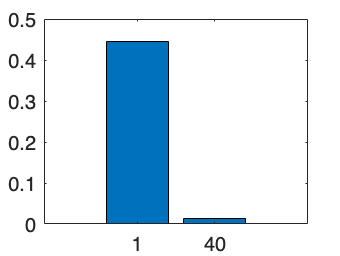

bar(timeBins, miValues);